# Testing Parameter Tuning

If you have a Simulink model for which you are planning to generate code and deploy in a context where parameters will be tuned, you probably want to test that!

In today's post, I will illustrate how this can be done using the [Parameter Writer](https://www.mathworks.com/help/releases/R2023b/simulink/slref/parameterwriter.html) block.

## The Question

Let's say I have this simple model:

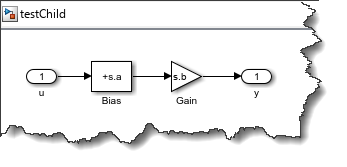

The Bias and Gain blocks are parameterized by a structure stored in the model workspace, and marked as [model argument](https://www.mathworks.com/help/releases/R2023b/simulink/ug/parameterize-referenced-models.html).

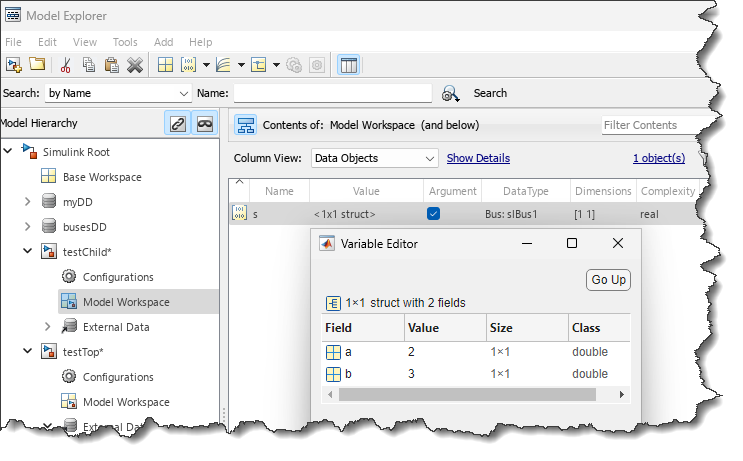

How can I test what happens if the value of `s.b` changes from 3 to 4 after 5 seconds of simulation?

## The Solution

To tune the parameter during the simulation, I can create a harness model where I will use a Parameter Writer block to overwrite the value of `s.b` while the simulation is running. Here is what the harness looks like:

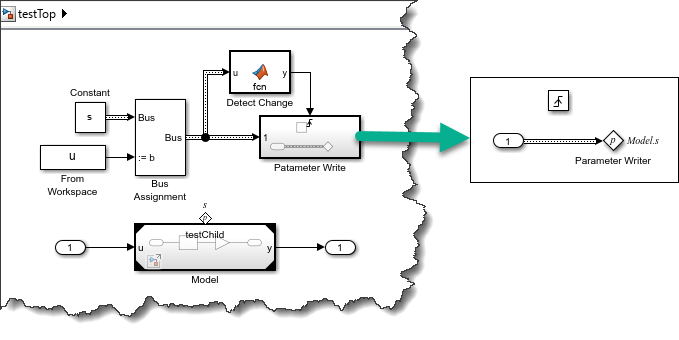

In this model, I use a Constant block with the same parameter structure as the variable `s` used in the model under test. I then use a [Bus Assignment](https://www.mathworks.com/help/releases/R2023b/simulink/slref/busassignment.html) block to overwrite the value of `s.b` with a new [timeseries](https://www.mathworks.com/help/releases/R2023b/matlab/ref/timeseries.html) coming from a From Workspace block.

u = timeseries([3 4],[0 5]);

I placed the Parameter Writer block inside a Triggered Subsystem, so it executes only when the parameter value changes. This is not mandatory but can help with performance.

In the Parameter Writer block, I select the parameter `s` from the Model block:

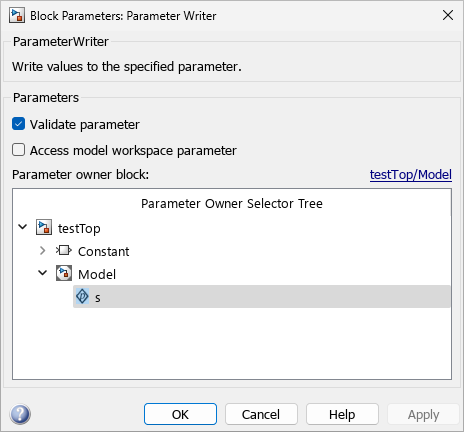

Once this is done, I can simulate the harness model and confirm that the parameter is being changed during the simulation:

in = Simulink.SimulationInput('testTop');
out=  sim(in);

### Starting serial model reference simulation build.
### Model reference simulation target for testChild is up to date.

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.6561s


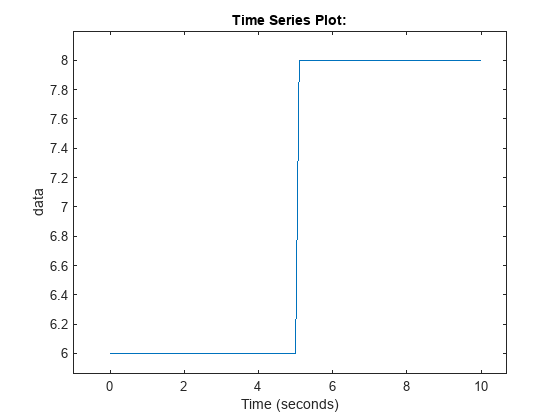

plot(out.yout{1}.Values);
axis padded

Combined with features from [Simulink Test](https://www.mathworks.com/products/simulink-test.html) to define the test and what needs to be assessed, this can be a convenient setup.

## Now it's your turn

How are you testing parameter tuning in your Simulink models? Let us know which techniques you are using in the comments below.

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2023_11_28_TestParameterTuning/2023_11_28_TestParameterTuning.prj)